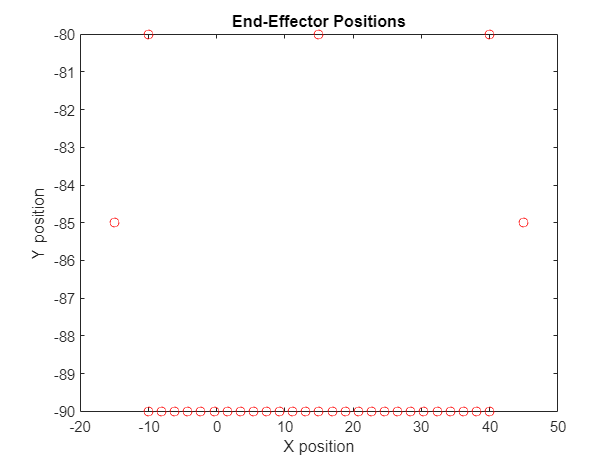

% Define the lengths of the femur and tibia bone
L1 = 73;  % length of femur bone
L2 = 26;  % length of tibia bone

%use function
num_points = 12*3;
[x_values, y_values] = oblong_shape(num_points,-10,40);



% [x_values, y_values] = triangular2_path(30,num_points,-30);
% [x_values, y_values] = square_path(10,num_points,-20);
% x_values = [0,0];
% y_values = [-99+0.0001,-99+0.0001];

% Compute the end-effector positions along the curve
end_effector_pos = zeros(2, length(x_values));
for i = 1:length(x_values)
    % Evaluate the curve function at the current parameter value
    x = x_values(i);
    y = y_values(i);
    end_effector_pos(:,i) = [x; y];
end

% Plot the end-effector positions
figure;
plot(end_effector_pos(1,:), end_effector_pos(2,:), 'ro');
xlabel('X position');
ylabel('Y position');
title('End-Effector Positions');


% Initialize arrays to store the computed angles
theta1 = zeros(1, length(x_values));
theta2 = zeros(1, length(x_values));

% Compute the inverse kinematics solution for each point along the curve
for i = 1:length(x_values)
    % Compute the distance between the end-effector and the knee joint
    d = norm(end_effector_pos(:,i));
    
    % Determine whether the end-effector is above or below the knee joint
    if d > L1 + L2
        % End-effector is out of reach
        error("No solution exists for the given end-effector position");
    elseif d < abs(L1 - L2)
        % End-effector is too close to the joint
        error("No solution exists for the given end-effector position");
    else
        % End-effector is within reach
        cos_theta2 = (-L1^2 - L2^2 + d^2) / (2 * L1 * L2);
        if abs(cos_theta2) > 1
            % No solution exists for the given end-effector position
            error("No solution exists for the given end-effector position");
        end
        if end_effector_pos(2,i) >= 0
            % End-effector is above the knee joint
            theta2(i) = acos(cos_theta2);
            theta1(i) = atan2(end_effector_pos(2,i), end_effector_pos(1,i)) - atan2(L2*sin(theta2(i)), L1+L2*cos(theta2(i)));
        else
            % End-effector is below the knee joint
            theta2(i) = -acos(cos_theta2);
            A=end_effector_pos(2,i)*(L1+L2*cos(theta2(i)))-end_effector_pos(1,i)*L2*sin(theta2(i));
            B=end_effector_pos(1,i)*(L1+L2*cos(theta2(i)))+end_effector_pos(2,i)*L2*sin(theta2(i));
        if B > 0
        theta1(i) = atan(A/B);
        else
        theta1(i) = atan(A/B) - pi;
        end
        end
    end
end

% Convert angles to degrees and adjust negative values
% Step 1: Rotate to align zero with North
theta1a=theta1-pi/2;
% Step 2: Reverse the direction of the angle
theta1a = -theta1a;

% Step 3: Make the angle positive
if theta1a < 0
    theta1a = theta1a + 360;
end

theta2a = theta2 + pi;

theta1_deg = flip(rad2deg(theta1a));
theta2_deg = flip(rad2deg(theta2a));

% Create string representations of the arrays
theta1_str = sprintf("int KneeAngleArray[] = {%d", round(theta1_deg(1)));
theta2_str = sprintf("int PawAngleArray[] = {%d", round(theta2_deg(1)));
for i = 2:length(theta1_deg)
    theta1_str = strcat(theta1_str, sprintf(",%d", round(theta1_deg(i))));
    theta2_str = strcat(theta2_str, sprintf(",%d", round(theta2_deg(i))));
end
theta1_str = strcat(theta1_str, "};");
theta2_str = strcat(theta2_str, "};");

% Display the results
% fprintf("Inverse Kinematics Solution:\n");
fprintf("%s\n", theta1_str)

int KneeAngleArray[] = {173,174,168,168,151,139,139,144,153,153,152,151,151,151,152,152,153,153,154,155,156,157,158,158,159,161,162,163,164,165,166,168,169,170,171,173};


fprintf("%s\n", theta2_str)

int PawAngleArray[] = {125,112,97,97,99,122,122,149,167,167,159,154,149,146,143,140,138,135,133,132,130,129,128,127,126,125,124,124,124,124,123,124,124,124,125,125};


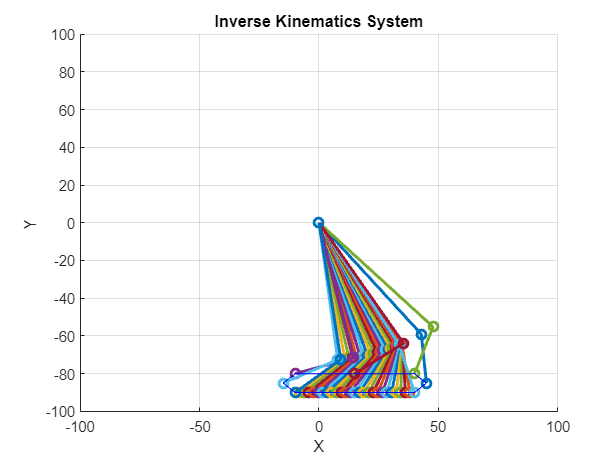


% Plot the end-effector positions and the links
% figure();
% hold on;
% plot(end_effector_pos(1,:), end_effector_pos(2,:), '-o', 'LineWidth', 2, 'MarkerSize', 8);
% for i = 1:length(theta1_deg)
%     % Compute the position of the knee joint
%     knee_pos = [L1 * cos(theta1(i)), L1 * sin(theta1(i))];
%     theta1_deg = rad2deg(theta1)
%     theta2_deg = rad2deg(theta2)
%     % Compute the position of the foot joint to x and y
%     % foot_pos = [L1 * cos(theta1(i)) + L2 * cos(theta1(i)+theta2(i)), L1 * sin(theta1(i)) + L2 * sin(theta1(i)+theta2(i))];
%     foot_pos = [knee_pos(1) + L2 * cos(theta1(i) + theta2(i)); knee_pos(2) + L2 * sin(theta1(i) + theta2(i))];
% 
%     % Plot the links
%     plot([0, knee_pos(1), foot_pos(1)], [0, knee_pos(2), foot_pos(2)], 'LineWidth', 2);
% end
% 
% figure;
% plot([0, knee_pos(1), foot_pos(1)], [0, knee_pos(2), foot_pos(2)], '-o', 'LineWidth', 2, 'MarkerSize', 8);
% xlim([-100, 100]);  % adjust as needed
% ylim([-100, 100]);  % adjust as needed
% title('2-DOF System');
% xlabel('X');
% ylabel('Y');
% grid on;
figure;
grid on; 
xlim([-100, 100]);  % adjust as needed
ylim([-100, 100]);  % adjust as needed
title('Inverse Kinematics System');
xlabel('X');
ylabel('Y');
hold on;

for i = 1:length(theta1_deg)
    % Compute the position of the knee joint
    knee_pos = [L1 * cos(theta1(i)), L1 * sin(theta1(i))];
    theta1_deg = rad2deg(theta1);
    theta2_deg = rad2deg(theta2);
    % Compute the position of the foot joint to x and y
    foot_pos = [knee_pos(1) + L2 * cos(theta1(i) + theta2(i)); knee_pos(2) + L2 * sin(theta1(i) + theta2(i))];

    % Plot the links
    plot([0, knee_pos(1), foot_pos(1)], [0, knee_pos(2), foot_pos(2)], '-o', 'LineWidth', 2);
    plot(end_effector_pos(1,:), end_effector_pos(2,:), 'b-');
end
hold off;

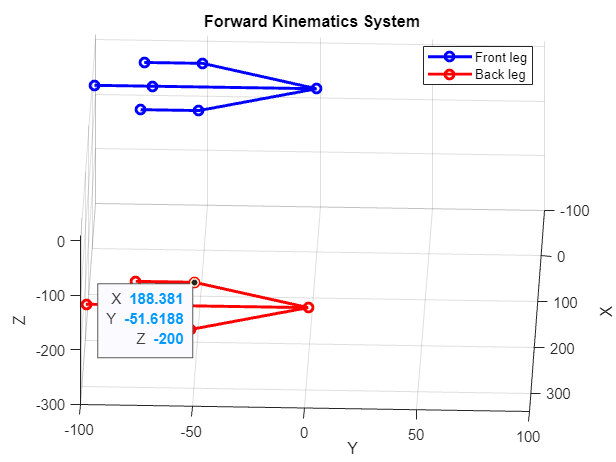

figure;
grid on;
xlim([-100, 340]);
ylim([-100, 100]);
zlim([-300, 10]); % Adjust the z limits as needed to view the back legs
title('Forward Kinematics System');
xlabel('X');
ylabel('Y');
zlabel('Z');
hold on;

theta1_strFK = "int FKneeAngleArray[] = {135,135,180,180,180,225,225,225,135};";
theta2_strFK = "int FPawAngleArray[] = {135,135,180,180,180,225,225,225,135};";

theta1_strBK = "int BKneeAngleArray[] = {135,135,180,180,180,225,225,225,135};";
theta2_strBK = "int BPawAngleArray[] = {135,135,180,180,180,225,225,225,135};";

offset_x = 240; % offset in x direction
offset_z = -200; % offset in z direction

[theta1_radF, theta2_radF] = parseStringArray(theta1_strFK, theta2_strFK);
[theta1_radB, theta2_radB] = parseStringArray(theta1_strBK, theta2_strBK);

% Ensure arrays have the same length
assert(length(theta1_radF) == length(theta2_radF) && length(theta1_radB) == length(theta2_radB), 'Angle arrays must have the same length');

for i = 1:length(theta1_radF)
    % Compute the position of the front knee joint
    knee_posF = [L1 * cos(theta1_radF(i)), L1 * sin(theta1_radF(i)), 0];
    % Compute the position of the front foot joint to x, y, and z
    foot_posF = [knee_posF(1) + L2 * cos(theta1_radF(i) + theta2_radF(i)), knee_posF(2) + L2 * sin(theta1_radF(i) + theta2_radF(i)), 0];

    % Compute the position of the back knee joint
    knee_posB = [L1 * cos(theta1_radB(i)) + offset_x, L1 * sin(theta1_radB(i)), offset_z];
    % Compute the position of the back foot joint to x, y, and z
    foot_posB = [knee_posB(1) + L2 * cos(theta1_radB(i) + theta2_radB(i)), knee_posB(2) + L2 * sin(theta1_radB(i) + theta2_radB(i)), offset_z];

    % Plot the links for both legs
    front_leg = plot3([0, knee_posF(1), foot_posF(1)], [0, knee_posF(2), foot_posF(2)], [0, 0, 0], '-o', 'LineWidth', 2, 'Color', 'b');
    back_leg = plot3([0 + offset_x, knee_posB(1), foot_posB(1)], [0, knee_posB(2), foot_posB(2)], [offset_z, offset_z, offset_z], '-o', 'LineWidth', 2, 'Color', 'r');
end

legend([front_leg, back_leg], {'Front leg', 'Back leg'});

% Adjust the view to top right
view(0,45);

function [theta1_rad, theta2_rad] = parseStringArray(theta1_str, theta2_str)
    % Parse the input strings to extract the arrays of angles
    theta1_deg = str2double(regexp(theta1_str, '\d+', 'match'));
    theta2_deg = str2double(regexp(theta2_str, '\d+', 'match'));

    % Convert angles from degrees to radians
    theta1_rad = deg2rad(theta1_deg);
    theta2_rad = deg2rad(theta2_deg);

    % adjust for the specific kinematic transformation in the original code
    % Step 1: Make the angle negative
    theta1_rad = -theta1_rad;

    % Step 2: Rotate to align zero with North
    theta1_rad = theta1_rad + pi/2;

    % Step 3: Make the angle positive
    theta1_rad = mod(theta1_rad, 2*pi);

    % For theta2 subtract pi
    theta2_rad = theta2_rad - pi;
end


% function [x_values, y_values] = oblong_shape(num_points,x_min,x_max)
% % Define the x and y values for the first straight line
% x_values1 = linspace(x_min, x_max, num_points/12); 
% y_values1 = -70*ones(1,num_points/12);
% 
% % Define the x and y values for the curve connecting (30,-50) to (30,-30)
% th1 = -pi/2:pi/((num_points/12)-1):pi/2;
% x_values2 = x_max + 10*cos(th1);
% y_values2 = -70 + 10*sin(th1);
% 
% % Define the x and y values for the second straight line
% x_values3 = linspace(x_max, x_min, 9*num_points/12);
% y_values3 = -70*ones(1,9*num_points/12);
% 
% % Define the x and y values for the curve connecting (30,-30) to (30,-50)
% th2 = pi/2:pi/((num_points/12)-1):3*pi/2;
% x_values4 = x_min + 10*cos(th2);
% y_values4 = -80 - 10*sin(th2);
% 
% % Combine the x and y values into one array
% x_values = [x_values1, x_values2, x_values3, x_values4];
% y_values = [y_values1, flip(y_values2), y_values3, y_values4];
% % x_values = [x_values1, x_values2, x_values3, x_values4];
% % y_values = [y_values1];
% end

function [x_values, y_values] = oblong_shape(num_points,x_min,x_max)
% Define the x and y values for the first straight line
x_values1 = linspace(x_min, x_max, 9*num_points/12); 
y_values1 = -90*ones(1,9*num_points/12);

% Define the x and y values for the curve connecting (30,-50) to (30,-30)
th1 = -pi/2:pi/((num_points/12)-1):pi/2;
x_values2 = x_max + 5*cos(th1);
y_values2 = -85 + 5*sin(th1);

% Define the x and y values for the second straight line
x_values3 = linspace(x_max, x_min, num_points/12);
y_values3 = -80*ones(1,num_points/12);

% Define the x and y values for the curve connecting (30,-30) to (30,-50)
th2 = pi/2:pi/((num_points/12)-1):3*pi/2;
x_values4 = x_min + 5*cos(th2);
y_values4 = -85 - 5*sin(th2);

% Combine the x and y values into one array
x_values = [x_values1, x_values2, x_values3, x_values4];
y_values = [y_values1, y_values2, y_values3, flip(y_values4)];
end

function [x_values, y_values] = square_path(side_length, num_points, y_offset)
    % Break up the total number of points into four segments
    points_per_segment = num_points / 4;

    % Define the x and y values for each of the four edges of the square
    x_values1 = linspace(-side_length/2, side_length/2, points_per_segment);
    y_values1 = (-side_length/2 + y_offset) * ones(1, points_per_segment);

    x_values2 = side_length/2 * ones(1, points_per_segment);
    y_values2 = linspace(-side_length/2 + y_offset, side_length/2 + y_offset, points_per_segment);

    x_values3 = linspace(side_length/2, -side_length/2, points_per_segment);
    y_values3 = (side_length/2 + y_offset) * ones(1, points_per_segment);

    x_values4 = -side_length/2 * ones(1, points_per_segment);
    y_values4 = linspace(side_length/2 + y_offset, -side_length/2 + y_offset, points_per_segment);

    % Combine the x and y values into one array
    x_values = [x_values1, x_values2, x_values3, x_values4];
    y_values = [y_values1, y_values2, y_values3, y_values4];
end

function [x_values, y_values] = triangular_path(base_length, height, num_points)
    % Break up the total number of points into three segments
    points_per_segment = num_points / 3;

    % Define the x and y values for each of the three edges of the triangle
    x_values1 = linspace(-base_length/2, base_length/2, points_per_segment);
    y_values1 = -height/2 * ones(1, points_per_segment);

    x_values2 = linspace(base_length/2, -base_length/2, points_per_segment);
    y_values2 = linspace(-height/2, height/2, points_per_segment);

    x_values3 = -base_length/2 * ones(1, points_per_segment);
    y_values3 = linspace(height/2, -height/2, points_per_segment);

    % Combine the x and y values into one array
    x_values = [x_values1, x_values2, x_values3];
    y_values = [y_values1, y_values2, y_values3];
end
function [x_values, y_values] = triangular2_path(base_length, num_points, y_offset)
    % Break up the total number of points into three segments
    points_per_segment = num_points / 3;

    % Calculate the height of the equilateral triangle
    height = sqrt(3) / 2 * base_length;

    % Define the x and y values for each of the three edges of the triangle
    x_values1 = linspace(-base_length/2, base_length/2, points_per_segment);
    y_values1 = (-height/2 + y_offset) * ones(1, points_per_segment);

    x_values2 = linspace(base_length/2, -base_length/2, points_per_segment);
    y_values2 = linspace(-height/2 + y_offset, height/2 + y_offset, points_per_segment);

    x_values3 = -base_length/2 * ones(1, points_per_segment);
    y_values3 = linspace(height/2 + y_offset, -height/2 + y_offset, points_per_segment);

    % Combine the x and y values into one array
    x_values = [x_values1, x_values2, x_values3];
    y_values = [y_values1, y_values2, y_values3];
end
